## **Farshad Bolouri **

## **R11630884**

## **Homework I**

clear
close all

### **Problem 4)**

**a)** Plots a single sinusoid with a fundamental frequency of 5/7 Hz over a time window of 30 seconds.  Use a very small step in the representation of time, to approximate a continuous-time signal. 

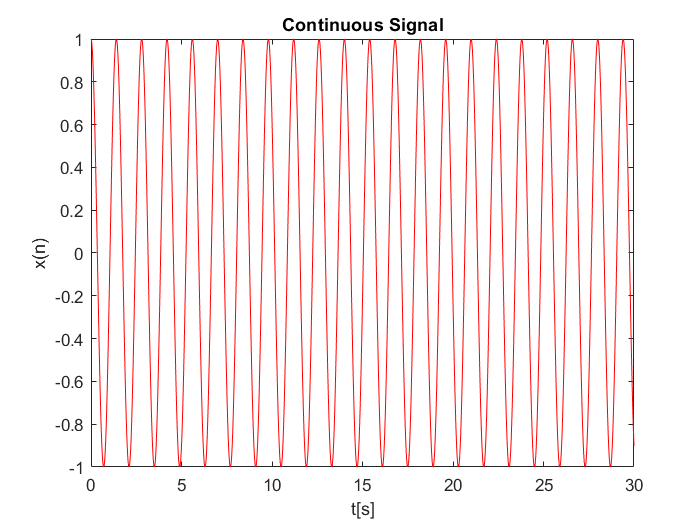

tmin = 0;     % start time [s]
tmax = 30;    % stop time [s]

f0 = 5/7;     % frequency of sinusoid

tc=tmin:0.001:tmax;     % Small step size
sinusoid = cos(2*pi*f0*tc);
plot(tc, sinusoid, 'r')
ylabel("x(n)")
xlabel("t[s]")
title("Continuous Signal")

**b)  **Simulate the sampling of the signal from a) at a sampling rate of 2/7 Hz. 

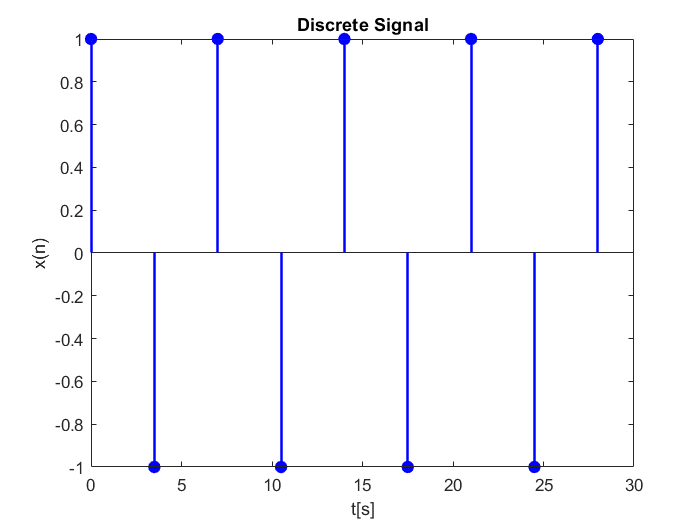

fs = 2/7;     % sampling frequency

td=tmin:1/fs:tmax;
discrete =cos(2*pi*f0*td);
stem(td,discrete, 'b' ,"filled", "LineWidth",1.5)
ylabel("x(n)")
xlabel("t[s]")
title("Discrete Signal")

**c) **Plots the discrete signal from b) on top of the continuous signal.  You can expect a plot similar to the following: 

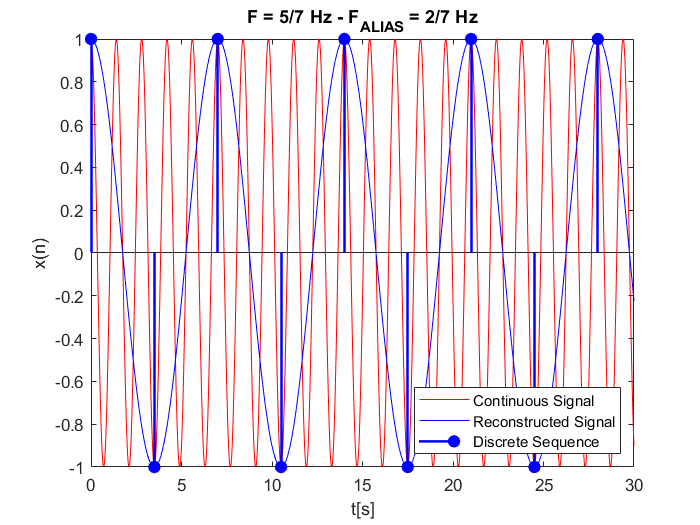

plot(tc, sinusoid, 'r')
hold on
falias = f0-2*fs;
reconstructed =cos(2*pi*falias*tc);
plot(tc , reconstructed, 'b')
stem(td,discrete, 'b' ,"filled", "LineWidth",1.5)
ylabel("x(n)")
xlabel("t[s]")
legend('Continuous Signal', 'Reconstructed Signal', 'Discrete Sequence', 'Location','southeast')
title("F = 5/7 Hz - F_{ALIAS} = 2/7 Hz")
hold off

**d) **Explain:  is aliasing happening? 

*Yes it is happenning! As it can be seen in the figure, the simulated signal is not a good represenation of the actual signal. the simulated signal is skipping many of the peaks in each cycle.*

*It is clear that our sampling rate is not sufficient enough and it is not meeting the minimum requirement (Nyquist rate).*

### **Problem 5)**

**a)** Generalize the solution of Problem 4 to support arbitrary sampling frequencies.   

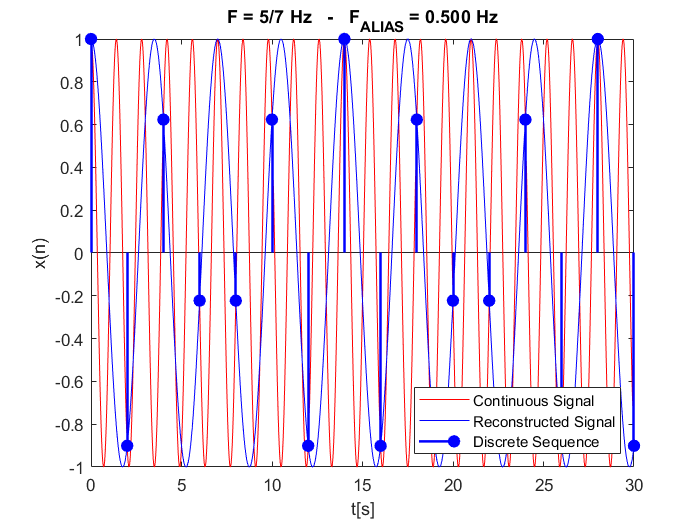

tmin = 0;     % start time [s]
tmax = 30;    % stop time [s]

f0 = 5/7;     % frequency of sinusoid
tc=tmin:0.001:tmax;     % Small step size
sinusoid = cos(2*pi*f0*tc);

prompt = ['Enter the sampling frequency:' newline '(No Fractions please - Ex: 0.5)'];
dlgtitle = 'Sampling Frequency';
fs = str2double(inputdlg(prompt,dlgtitle));
td=tmin:1/fs:tmax;
discrete =cos(2*pi*f0*td);

plot(tc, sinusoid, 'r')
hold on
falias = f0-2*fs;
reconstructed =cos(2*pi*falias*tc);
plot(tc , reconstructed, 'b')
stem(td,discrete, 'b' ,"filled", "LineWidth",1.5)
ylabel("x(n)")
xlabel("t[s]")
legend('Continuous Signal', 'Reconstructed Signal', 'Discrete Sequence', 'Location','southeast')
title(sprintf("F = 5/7 Hz   -   F_{ALIAS} = %.3f Hz", fs))
hold off

**b)** Generate plots for three cases:  under-sampled, over-sampled, and critically sampled.   Explain the behavior. 

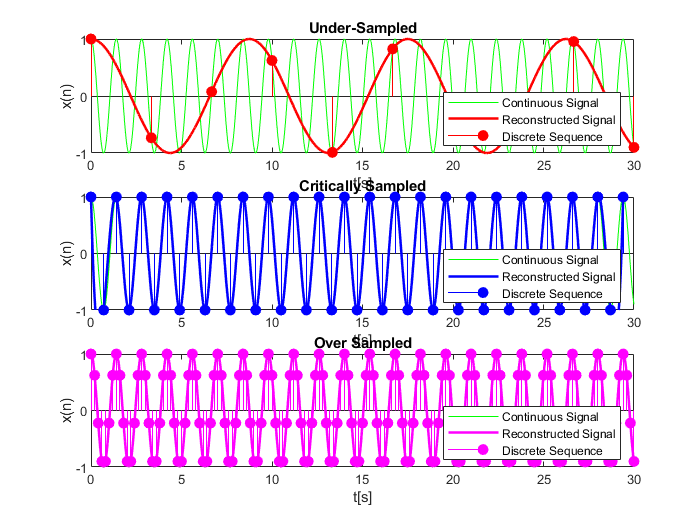

figure
% Under-Sampled
subplot(3,1,1)
plot(tc, sinusoid, 'g')
hold on
fs_under = 0.3;
td=tmin:1/fs_under:tmax;
falias_under = f0-2*fs_under;
discrete =cos(2*pi*f0*td);
reconstructed =cos(2*pi*falias_under*tc);
plot(tc , reconstructed, 'r', "LineWidth",1.5)
stem(td,discrete, 'r' ,"filled")
ylabel("x(n)")
xlabel("t[s]")
legend('Continuous Signal', 'Reconstructed Signal', 'Discrete Sequence', 'Location','southeast')
title("Under-Sampled")
hold off

% Critically Sampled
subplot(3,1,2)
plot(tc, sinusoid, 'g')
hold on
fs_critical = 2*f0; % Nyquist Rate
td=tmin:1/fs_critical:tmax;
discrete =cos(2*pi*f0*td);
reconstructed = interp1(td,discrete,tc,'spline');
plot(tc , reconstructed, 'b', "LineWidth",1.5)
stem(td,discrete, 'b' ,"filled")
ylabel("x(n)")
xlabel("t[s]")
ylim([-1 1])
legend('Continuous Signal', 'Reconstructed Signal', 'Discrete Sequence', 'Location','southeast')
title("Critically Sampled")
hold off

% Over-Sampled
subplot(3,1,3)
plot(tc, sinusoid, 'g')
hold on
fs_over = 5;
td=tmin:1/fs_over:tmax;
discrete =cos(2*pi*f0*td);
reconstructed = interp1(td,discrete,tc,'spline');
plot(tc , reconstructed, 'm', "LineWidth",1.5)
stem(td,discrete, 'm' ,"filled")
ylabel("x(n)")
xlabel("t[s]")
legend('Continuous Signal', 'Reconstructed Signal', 'Discrete Sequence', 'Location','southeast')
title("Over Sampled")
ylim([-1 1])
hold off
set(gcf,'Visible','on')

- **Under-Sampled: ***As it can be seen in the figure, the simulated signal is not a good represenation of the actual signal. the simulated signal is skipping many of the peaks in each cycle. It is clear that our sampling rate is not sufficient enough and it is not meeting the minimum requirement (Nyquist rate).*

- ***Critically Sampled: ****The reconstructed signal is fitting the original signal well as the sampling rate is following the Nyquist Rate.*

- ***Over-Sampled: ****The reconstructed signal is fitting the original signal very well as the sampling rate is much higher than the required Nyquist Rate. *

**c) **Find two different sampling frequencies for which your discrete samples are identical.  Can you explain under which conditions will this happen?

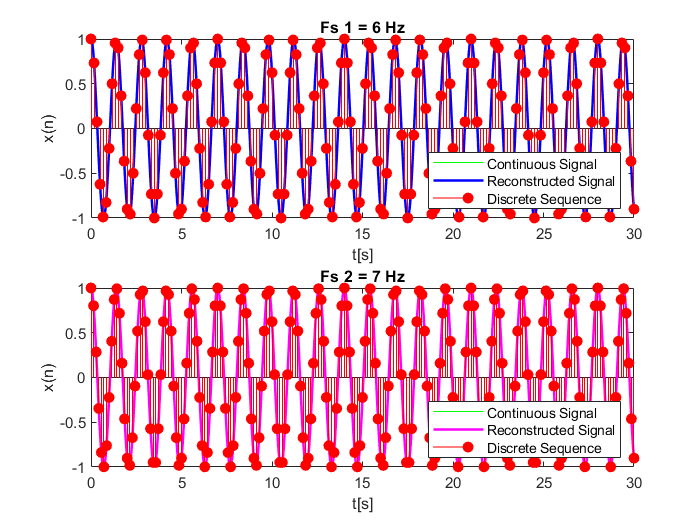

figure
% Frequency 1
subplot(2,1,1)
plot(tc, sinusoid, 'g')
hold on
fs1 = 6;
td=tmin:1/fs1:tmax;
discrete =cos(2*pi*f0*td);
reconstructed = interp1(td,discrete,tc,'spline');
plot(tc , reconstructed, 'b', "LineWidth",1.5)
stem(td,discrete, 'r', "filled")
ylabel("x(n)")
xlabel("t[s]")
ylim([-1 1])
legend('Continuous Signal', 'Reconstructed Signal', 'Discrete Sequence', 'Location','southeast')
title("Fs 1 = 6 Hz")
hold off

% Frequency 2
subplot(2,1,2)
plot(tc, sinusoid, 'g')
hold on
fs2 = 7;
td=tmin:1/fs2:tmax;
discrete =cos(2*pi*f0*td);
reconstructed = interp1(td,discrete,tc,'spline');
plot(tc , reconstructed, 'm', "LineWidth",1.5)
stem(td,discrete, 'r' ,"filled")
ylabel("x(n)")
xlabel("t[s]")
ylim([-1 1])
legend('Continuous Signal', 'Reconstructed Signal', 'Discrete Sequence', 'Location','southeast')
title("Fs 2 = 7 Hz")
hold off
set(gcf,'Visible','on')

*As it can be seen in the two figures, the reconstrcuted signals look identical as they are both fitting the original signal very well, even though they are sampled at different frequencies. This is happenning because, both sampling frequencies are ****much higher than the Nyquist Rate****. When they are both much higher than the required rate, then they both going to look identical as they both are fitting the same signal.*

### Problem 6)

**a) **Modify the test continuous signal to include multiple frequencies (at least 3, make sure that they are not multiples of each other). 

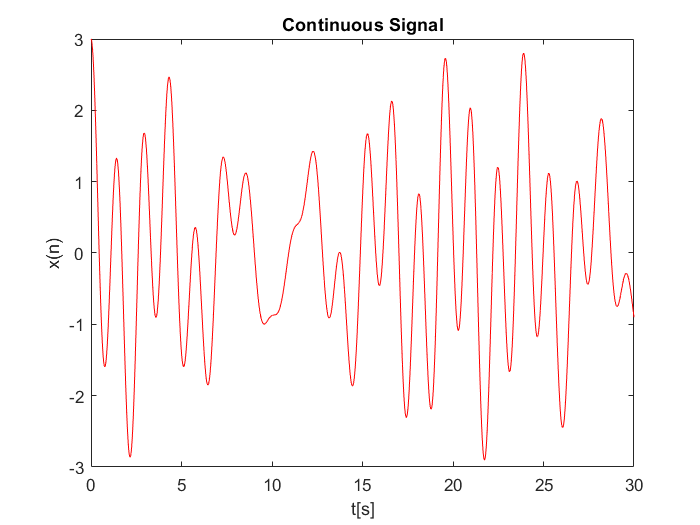

figure
f01 = 2/3;
f02 = 5/7;
f03 = 1/4;

sinusoid = cos(2*pi*f01*tc) + cos(2*pi*f02*tc) + cos(2*pi*f03*tc);

plot(tc, sinusoid , 'r')
ylabel("x(n)")
xlabel("t[s]")
title("Continuous Signal")

**b) **Sample the test signal using a sampling frequency that is higher than the maximum signal frequency in your input signal. 

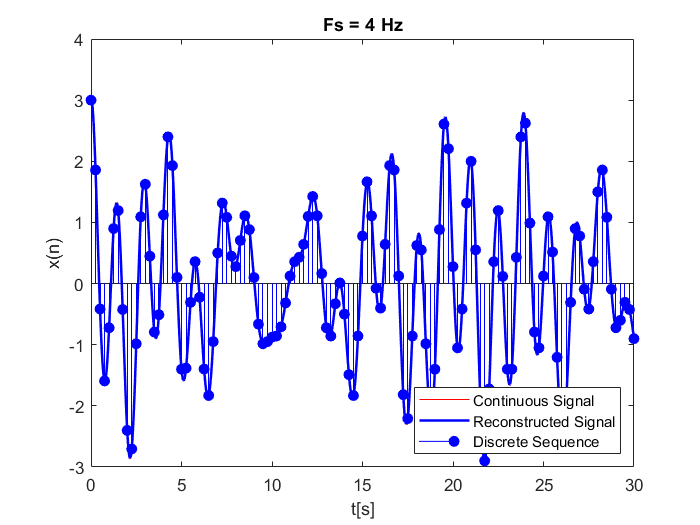

plot(tc, sinusoid , 'r')
hold on
fs = 4;
td=tmin:1/fs:tmax;
discrete =cos(2*pi*f01*td) + cos(2*pi*f02*td) + cos(2*pi*f03*td);
reconstructed = interp1(td,discrete,tc,'spline');
plot(tc , reconstructed, 'b', "LineWidth",1.5)
stem(td,discrete, 'b' ,"filled")
ylabel("x(n)")
xlabel("t[s]")
legend('Continuous Signal', 'Reconstructed Signal', 'Discrete Sequence', 'Location','southeast')
title("Fs = 4 Hz")
hold off

**c)** Determine the dynamic range of the sampled signal (minimum and maximum amplitudes) and normalize it to [-1, 1]. 

max_Amp = max(discrete);
min_Amp = min(discrete);
dynamic_range = [min_Amp max_Amp];
fprintf("The dynamic range is from %.3f to %d", dynamic_range(1),dynamic_range(2))

The dynamic range is from -2.899 to 3

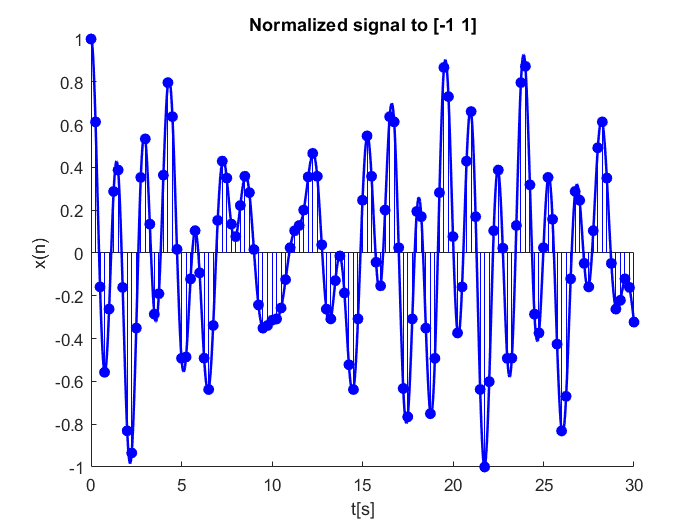

% Normalzing to -1 to 1
discrete_norm = (discrete-min(discrete))/range(discrete)*2-1;
reconstructed_norm = (reconstructed-min(reconstructed))/range(reconstructed)*2-1;

figure
hold on
plot(tc , reconstructed_norm, 'b', "LineWidth",1.5)
stem(td,discrete_norm, 'b' ,"filled")
ylabel("x(n)")
xlabel("t[s]")
title("Normalized signal to [-1 1]")
hold off

max_Amp_norm = max(discrete_norm);
min_Amp_norm = min(discrete_norm);
new_dynamic_range = [min_Amp_norm max_Amp_norm];
fprintf("The new dynamic range is from %.3f to %d", new_dynamic_range(1),new_dynamic_range(2))

The new dynamic range is from -1.000 to 1

**d) **Quantize the sampled signal with a resolution of b=8 bits.   Compute the absolute value of the difference between your quantized signal and the original signal (this is your measured quantization noise).   Compute the average measured quantization noise and convert it to dB.  Compare with the expected amount of noise according to the formula (1.76+6.02*b) dB. 

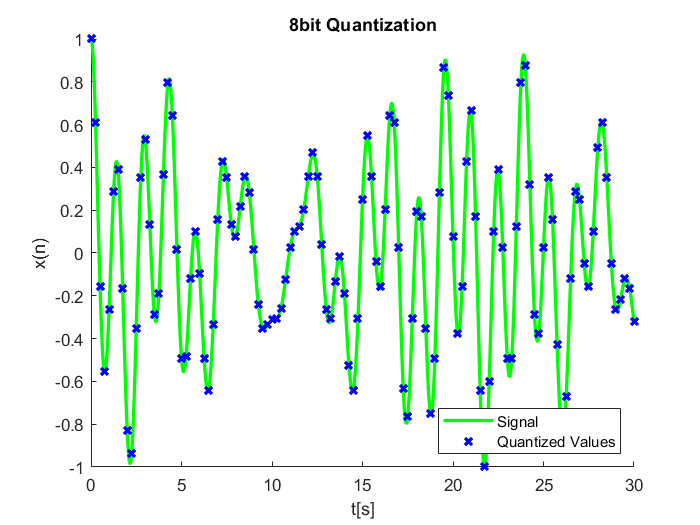

nbits = 8; % 256 qantization levels
qLevels = 2^nbits; 

% scaling the signal to have the same magnitude as the number of bits
scalingFactor = (max_Amp_norm-min_Amp_norm)/qLevels;
discrete_norm_quantized = discrete_norm / scalingFactor;

% the signal is now ranging from -128 to 128
% round() is used to quantize the signal
% then the signal is scaled back to its original magnititude
discrete_norm_quantized = round(discrete_norm_quantized);
discrete_norm_quantized = discrete_norm_quantized * scalingFactor;

figure
hold on
plot(tc , reconstructed_norm, 'g', "LineWidth",2)
plot(td,discrete_norm_quantized, 'bx', 'LineWidth', 2)
ylabel("x(n)")
xlabel("t[s]")
title("8bit Quantization")
legend('Signal', 'Quantized Values', 'Location','southeast')
hold off


QError = abs(mag2db(mean(abs(discrete_norm - discrete_norm_quantized))));
fprintf("Quantization error is = %0.3f dB", QError)

Quantization error is = 53.861 dB

fprintf("According to the formula the noise is equal to :\n 1.76+6.02*8 = %0.2f", 1.76+6.02*8);

According to the formula the noise is equal to :
 1.76+6.02*8 = 49.92

fprintf("The error between is the Quantization error and the formula's result is %0.2f percent", ...
    100*(abs(QError - (1.76+6.02*8))/(1.76+6.02*8)));

The error between is the Quantization error and the formula's result is 7.90 percent

**d) **For the following values of b: b=2, 4, 16.   Do your measurements match the formula for big and small values of b? 

b = [2, 4, 16, 24 , 32, 40];
QError = zeros(1,6);
percentError = zeros(1,6);
for i = 1:6
    nbits = b(i); % 256 qantization levels
    qLevels = 2^nbits;
    
    % scaling the signal to have the same magnitude as the number of bits
    scalingFactor = (max_Amp_norm-min_Amp_norm)/qLevels;
    discrete_norm_quantized = discrete_norm / scalingFactor;
    
    % the signal is now ranging from -128 to 128
    % round() is used to quantize the signal
    % then the signal is scaled back to its original magnititude
    discrete_norm_quantized = round(discrete_norm_quantized);
    discrete_norm_quantized = discrete_norm_quantized * scalingFactor;
    
    QError(i) = abs(mag2db(mean(abs(discrete_norm - discrete_norm_quantized))));
    percentError(i) = 100*(abs((QError(i) - (1.76+6.02*b(i)))/(1.76+6.02*b(i))));
end

fprintf("At b = 2, the Quantization noise is = %0.3f dB", QError(1))

At b = 2, the Quantization noise is = 17.666 dB

fprintf("According to the formula the noise is equal to :\n 1.76+6.02*2 = %0.2f dB", 1.76+6.02*2);

According to the formula the noise is equal to :
 1.76+6.02*2 = 13.80 dB

fprintf("At b = 2, the error between is the Quantization noise and the formula's result is %0.2f percent", percentError(1))

At b = 2, the error between is the Quantization noise and the formula's result is 28.01 percent

fprintf("At b = 4, the Quantization Noise is = %0.3f dB", QError(2))

At b = 4, the Quantization Noise is = 31.575 dB

fprintf("According to the formula the noise is equal to :\n 1.76+6.02*4 = %0.2f dB", 1.76+6.02*4);

According to the formula the noise is equal to :
 1.76+6.02*4 = 25.84 dB

fprintf("At b = 4, the error between is the Quantization noise and the formula's result is %0.2f percent", percentError(2))

At b = 4, the error between is the Quantization noise and the formula's result is 22.19 percent

fprintf("At b = 16, the Quantization noise is = %0.3f dB", QError(3))

At b = 16, the Quantization noise is = 104.462 dB

fprintf("According to the formula the noise is equal to :\n 1.76+6.02*16 = %0.2f dB", 1.76+6.02*16);

According to the formula the noise is equal to :
 1.76+6.02*16 = 98.08 dB

fprintf("At b = 16, the error between is the Quantization noise and the formula's result is %0.2f percent", percentError(3))

At b = 16, the error between is the Quantization noise and the formula's result is 6.51 percent

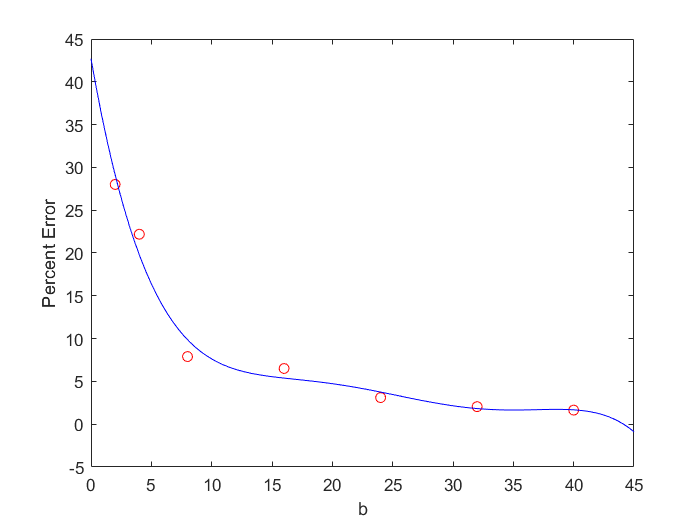


% Trend of the Quantization Error with respect to value of b
b = [2, 4, 8, 16, 24, 32, 40];
percentError = [percentError(1:2) 7.90 percentError(3:end)];

x = linspace(0,45);
p = polyfit(b, percentError, 5);
interpolated = polyval(p,x);
plot(b,percentError,'ro',x,interpolated,'b');
xlabel("b");
ylabel("Percent Error")

We can see that as the value of **b** gets bigger our percent error gets smaller --> Our Quantization noise gets smaller.